%Load Pre-Trained GoogleNet
clc
clear
Net = googlenet;
layers = Net.Layers;

%Read Dataset and Knowing Categories
path = fullfile(pwd);
filepath = [path,filesep,'Gender Classification'];
imds = imageDatastore(filepath,...  
    'IncludeSubfolders',true,...
    'LabelSource','foldernames'); 
label_class = unique(imds.Labels)

label_class = 2×1 categorical array
     Female 
     Male 


Categories = length(label_class);

% A=imds.Files(1);
% B=imread(A{1,1})
% C=imresize(B,[227 227]);
% imshow(C)

% We look at the first layer to see the size requirement
sizeRequirement = Net.Layers(1).InputSize;
inputSize = sizeRequirement(1:2)

inputSize =    224   224



% % Create anonymous function
imds.ReadFcn = @(img) imresize(imread(img),inputSize);

%Splitting Train, Test, and Validation Dataset
[trainDS, valDS, testDS] = splitEachLabel(imds,0.7,0.15,0.15,'randomized');

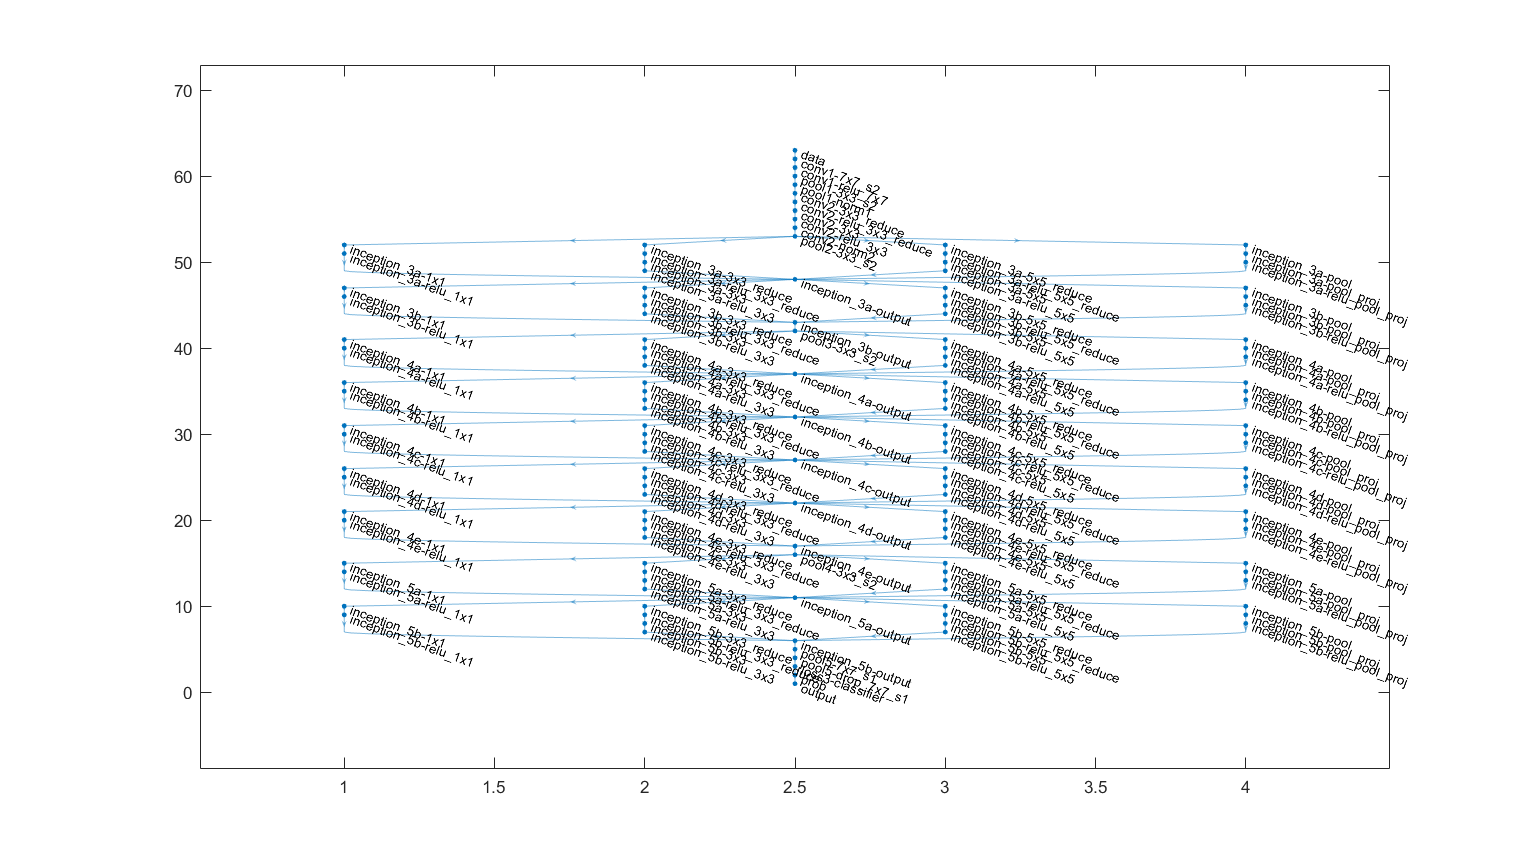

lgraph = layerGraph(Net);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)

lgraph = removeLayers(lgraph, {'loss3-classifier','prob','output'});

numClasses = numel(categories(trainDS.Labels));
newLayers = [
    fullyConnectedLayer(numClasses,'Name','fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];
lgraph = addLayers(lgraph,newLayers);

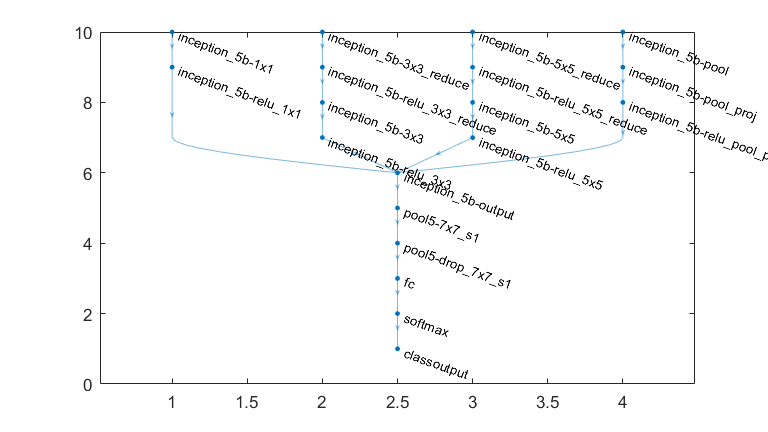

lgraph = connectLayers(lgraph,'pool5-drop_7x7_s1','fc');

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

%Hyperparameter tuning
trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',0.001,...
    'ValidationData',valDS,...
    'Plots','training-progress',...
    'MiniBatchSize', 50,...
    'ValidationPatience', 3);

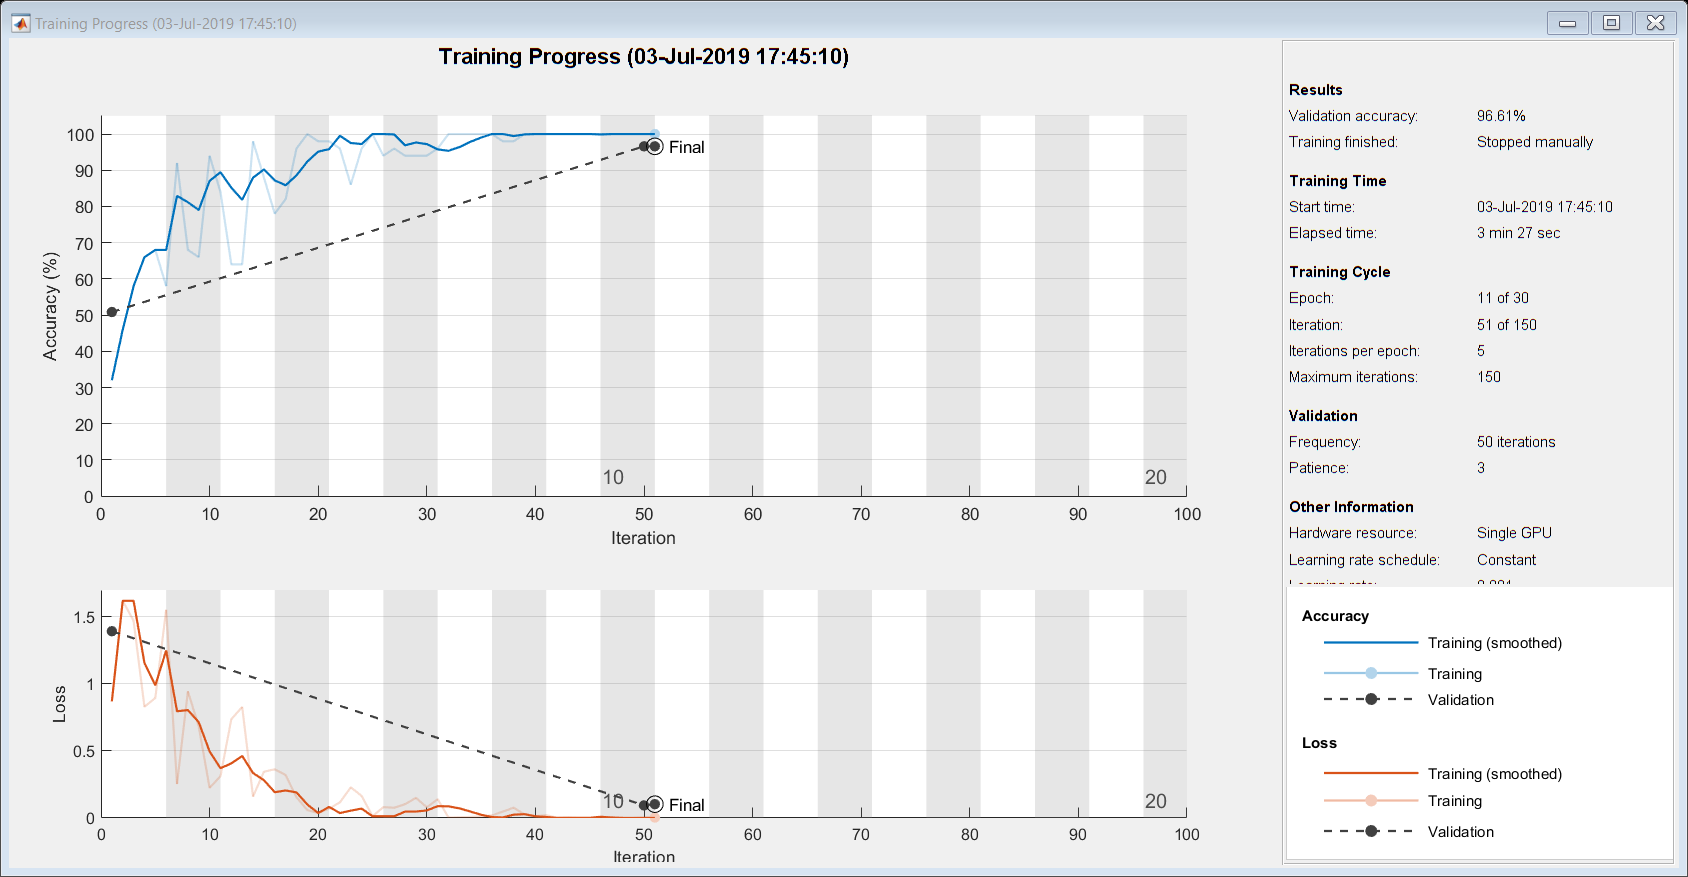

Training on single GPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       32.00% |       50.85% |       0.8701 |       1.3934 |          0.0010 |
|      10 |          50 |       00:03:20 |      100.00% |       96.61% |       0.0039 |       0.0939 |          0.0010 |
|      11 |          51 |       00:03:27 |      100.00% |              |       0.0035 |              |          0.0010 |
|======================================================================================================================

Net = trainNetwork(trainDS,lgraph,trainOpts);

save GoogleNetTransferLearning Net

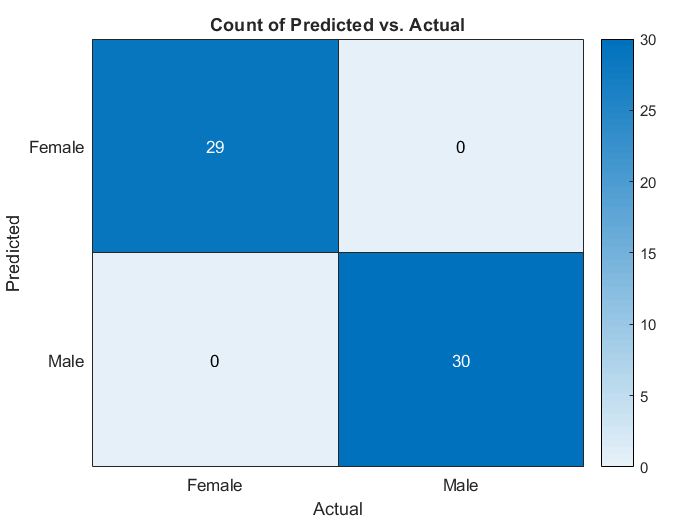

%Testing
doTest = true;

if doTest
    [labels, scores] = classify(Net, testDS);
else
    load testResults.mat 
end

% Calculate accuracy
accuracy = sum(labels == testDS.Labels)/numel(labels);

% Confusion Matrix - visual inspection of accuracy and error
tbl = table(labels,testDS.Labels,...
    'VariableNames', {'Predicted', 'Actual'});

figure('name','Confusion Matrix')
heatmap(tbl,'Actual','Predicted');


% Are there trends in the misclassifications?
% Where might these come from?

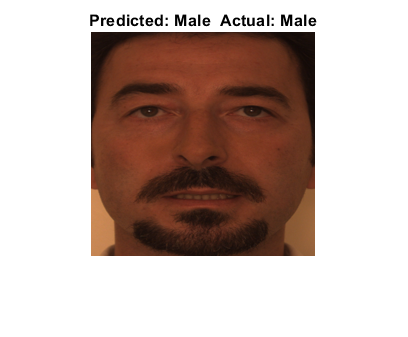


randNum = randi(length(testDS.Files));
imOriginal = readimage(testDS,randNum);
imResized = imresize(imOriginal, inputSize);

actualLabel = testDS.Labels(randNum);
predictedLabel = classify(Net,imResized);
imshow(imOriginal)
title(['Predicted: ' char(predictedLabel) '  Actual: ' char(actualLabel)],'Interpreter','none')